# モデル予測制御による車両の横方向制御

本例では、車両の横方向制御を例にモデル予測制御による設計事例を示す。

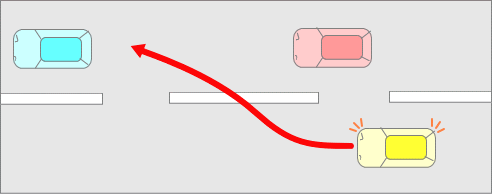

制御対象は線形な車両の横方向運動に関する以下のダイナミクスを取り扱う。


$$\frac{d}{d\;t}\left\lbrack \begin{array}{c}
\dot{y} \\
\psi \\
\psi^˙ \\
Y
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
-\frac{2C_f +2C_r }{m*V_x } & 0 & -V_x -\frac{2C_f l_f -2C_r l_r }{m*V_x } & 0\\
0 & 0 & 1 & 0\\
-\frac{2C_f l_f -2C_r l_r }{I_z *V_x } & 0 & -\frac{2C_f {l_f }^2 +2C_r {l_r }^2 }{I_z *V_x } & 0\\
1 & V_x  & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{y} \\
\psi \\
\psi^˙ \\
Y
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\frac{2C_f }{m}\\
0\\
\frac{2C_f l_f }{I_z }\\
0
\end{array}\right\rbrack \delta$$


横方向に関する状態量は、横方向位置$Y$、横方向速度$\dot{y} \left(=V_y \right)$、ヨー角$\psi$、ヨー角速度$\psi^˙$の4つとし、

このうち観測し、かつ制御するのは横方向位置とヨー角の2つとする。

操作量はステアリング舵角$\delta$を使用する。

またモデルは縦方向速度$V_x$によってシステムの挙動が変化するLTV(Linear Time Variant)システムであるとし、

線形なモデル予測制御と適応モデル予測制御を各々適用した際に制御結果がどのように異なるかを比較する。

シミュレーションでは、車両の横方向位置に関し、初期位置から4[m]の変位指令とそれに見合うヨー角指令を与える。

その間、車両の縦方向速度はSin上に増減する。

clc,clear
addpath('.\libForAMPC')
load Params.mat
open_system('AMPC_TEST')

予測モデルを設定する。

% Predictive model
Ts = 0.1;               %サンプリング時間
Vx = 15;                %初期縦方向速度
x0 = [0;0;0;0];         %初期状態量ベクトル
u0 = 0;                 %初期操作量
[A,B,Bd,C,U,MD,Y,X,f0] = calcPlantModelDT(Ts,Vx,u0,x0); %初期操作点における線形システム
sysm.A = A;
sysm.B = B;
sysm.C = C;

MPC制御パラメーターを設定する。

% Control params
params.Q = diag([2.8292,0.2829]);       %出力の重み
params.R = 0.0353;                      %入力の重み
params.PredictiveHorizon = 10;          %予測ホライズン
params.ControlHorizon = 5;              %制御ホライズン
params.MV_max = 30*pi/180;              %入力制約
params.MV_min = -30*pi/180;
params.dMV_max = 10*pi/180*Ts;          %入力変化率制約
params.dMV_min = -10*pi/180*Ts;
params.OV_max = [10;0.2];               %出力制約
params.OV_min = [-10;-0.2];
params.MV_scalefactor = 30*pi/180;      %入力のスケールゲイン

AMPCにて必要となるバスオブジェクトは専用のAPIを使用してワークスペースに作成できる。

% Create sysBus object
n = size(A,1);          %状態量の次数
m = size(B,2);          %操作量の次数
l = size(C,1);          %出力の次数
nd = 0;                 %外乱の次数
sysBus = createSysBusObject(n,m,nd,l);

シミュレーションを実行する。

% Simulation
Tsim = 15;
tic
sim('AMPC_TEST',Tsim);
toc

経過時間は 1.939142 秒です。


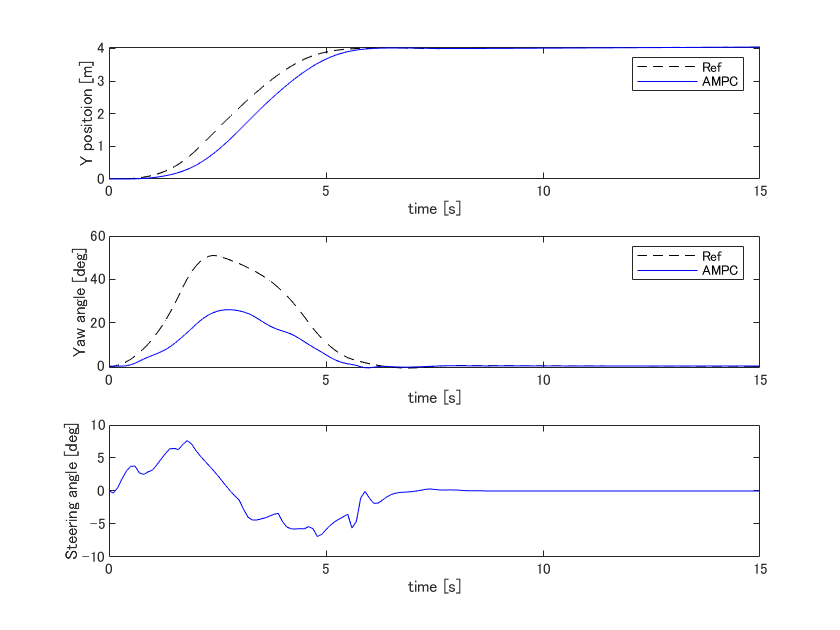

% Plot simulation results
% Results of AMPC
figure(1),clf
subplot(3,1,1)
plot(AMPCdata.time,AMPCdata.signals(1).values(:,2),'k--'),hold on
plot(AMPCdata.time,AMPCdata.signals(1).values(:,1),'b-'),hold on
xlabel('time [s]')
ylabel('Y positoion [m]')
legend('Ref','AMPC')
subplot(3,1,2)
plot(AMPCdata.time,(180*pi)*AMPCdata.signals(2).values(:,2),'k--'),hold on
plot(AMPCdata.time,(180*pi)*AMPCdata.signals(2).values(:,1),'b-'),hold on
xlabel('time [s]')
ylabel('Yaw angle [deg]')
legend('Ref','AMPC')
subplot(3,1,3)
plot(AMPCdata.time,(180*pi)*AMPCdata.signals(3).values(:,1),'b-'),hold on
xlabel('time [s]')
ylabel('Steering angle [deg]')

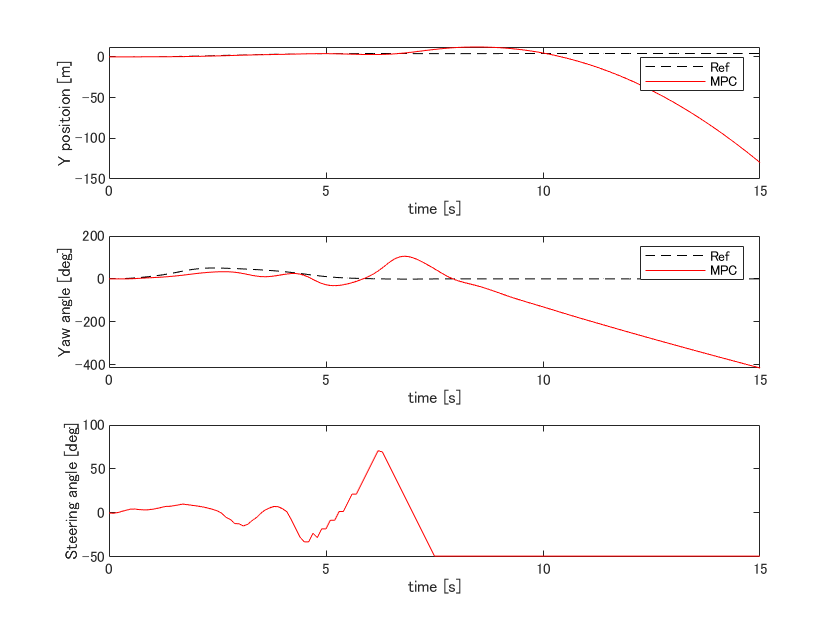

% Results of MPC
figure(2),clf
subplot(3,1,1)
plot(AMPCdata.time,AMPCdata.signals(1).values(:,2),'k--'),hold on
plot(MPCdata.time,MPCdata.signals(1).values(:,1),'r-'),hold off
xlabel('time [s]')
ylabel('Y positoion [m]')
legend('Ref','MPC')
subplot(3,1,2)
plot(AMPCdata.time,(180*pi)*AMPCdata.signals(2).values(:,2),'k--'),hold on
plot(MPCdata.time,(180*pi)*MPCdata.signals(2).values(:,1),'r-'),hold off
xlabel('time [s]')
ylabel('Yaw angle [deg]')
legend('Ref','MPC')
subplot(3,1,3)
plot(MPCdata.time,(180*pi)*MPCdata.signals(3).values(:,1),'r-'),hold off
xlabel('time [s]')
ylabel('Steering angle [deg]')

以上の結果から、AMPCでは車両の縦方向速度の変化に伴うダイナミクスの変動に対し、適応して制御を行うことが出来るが、

通常のMPCでは、ノミナル点のみのプラントであるためにダイナミクスの変化に追従できず制御が発散することが比較できる。

参考：

MathWorks Webinor : Understanding Model Predictive Control, Part 7: Adaptive MPC Design with Simulink and Model Predictive Control Toolbox 

[https://jp.mathworks.com/videos/understanding-model-predictive-control-part-7-adaptive-mpc-design-with-simulink-and-model-predictive-control-toolbox--1539762605717.html](https://jp.mathworks.com/videos/understanding-model-predictive-control-part-7-adaptive-mpc-design-with-simulink-and-model-predictive-control-toolbox--1539762605717.html)